## Test code

## parameters (mm)

%{
% objective
obj = [60, 0, -50]';

% lens
f = 50;  % focal length
D = 50; % lens diameter

% DMD
dmd_pos = 50;
dmd_size = [50,50]';

% mask
mask_pos = 100;
mask_size = [50,50]';
%}

% add path
addpath('./utils');

% test sub2coord.m
element_idx = [1 3]';
% element_idx = [1.5,1.5]';
% element_idx = [2,2]';
% element_idx = [3,3]';
mat_sz = [3,3]';
% mat_sz = [4,4]';
element_sz = 1;
coord = sub2coord(element_idx, mat_sz, element_sz) % xy coordinate system direction(right,up)
% coord = sub2coord(element_idx, mat_sz, element_sz, 'mn') % mn coordinate system direction(down,right)

% test coord2sub.m
% coord = [-0.1,0.1]';
% coord = [0.4, 0.4]';
coord = [-0.2 0.6]';
mat_sz = [3,3]';
% mat_sz = [2,2]';
element_sz = 1;
element_idx = coord2sub(coord, mat_sz, element_sz)% xy coordinate system direction(right,up)
% element_idx = coord2sub(coord, mat_sz, element_sz, 'mn') % mn coordinate system direction(down,right)

% test dist_map.m
distance_map = dist_map([4,4], [1,1], [0,0])

% test point_img.m

obj = [60, 0, -50]';
img = point_img(obj,f)

obj = [60, 60, -100]';
img = point_img(obj,f)

obj = [60, 0, -10000]';
img = point_img(obj,f)


% test blur_spot.m
clc
% obj
obj = [60, 0, -100]';
% lens
f = 50;  % focal length
D = 50; % lens diameter
% DMD
% dmd_pos = 0.0001;
dmd_pos = 0;
% dmd_pos = 50; %
% mask
mask_pos = 100; % image plane
% mask_pos = 70;

dmd_spot_center = blur_spot(obj, f, D, dmd_pos)
% [dmd_spot_center, dmd_spot_r] = blur_spot(obj, f, D, dmd_pos)
[mask_spot_center, mask_spot_r] = blur_spot(obj, f, D, mask_pos)

% test binary_mask.m
sz = [100,100];
transmission_rate = 0.2;
x=binary_mask(sz, transmission_rate);
imshow(x)
true_one_prob = sum(sum(x))/10000

% test mask_transmit_ratio
clc
mask_pix_size = 1;
% mask = binary_mask([20, 20], 0.5);
% mask1 = binary_mask([100, 100], 0.5);
% mask2 = binary_mask([50, 50], 0.5);
% mask = binary_mask(15, 0.5);
% mask = zeros(15); mask(8,8)=1;
% mask = [1 0; 0 1]
% mask = [1 1 0; 0 1 0; 1 0 1]

% spot_p = [0.7 0.7]'
spot_p = [-7 9]'

spot_p =     -7
     9


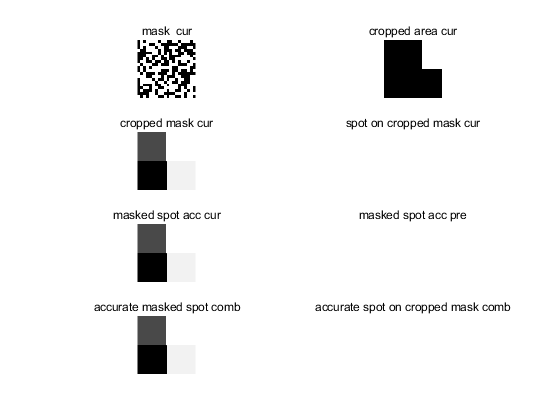

% spot_p1 = randi(100,[2 1]) - 50
% spot_p2 = randi(50,[2 1]) - 25
% spot_p = [2,8.3]'
% spot_r1 = 30.2/2; % mask on image plane
% spot_r2 = 20/2; % mask on image plane
spot_r = 5;

resampling_factor1 = 100;
resampling_factor2 = 50;

% resampling_scale = mask_pix_size/(2*spot_r/resampling_factor)
% least_size = resampling_scale^2

[trans_ratio, masked_spot] = mask_propagate2(mask, mask_pix_size, spot_p, spot_r,'test','mn');

% trans_ratio = mask_propagate(mask, mask_pix_size, spot_p, spot_r)
% [trans_ratio1, masked_spot1] = mask_propagate(mask1, mask_pix_size, spot_p1, spot_r1,resampling_factor1,'test','mn');
% [trans_ratio2, masked_spot2] = mask_propagate(mask2, mask_pix_size, spot_p2, spot_r2,resampling_factor2,logical(masked_spot1),'mn','test');
% [trans_ratio] = mask_propagate(mask, mask_pix_size, spot_p, spot_r,resampling_factor,'mn',true);
trans_ratio

trans_ratio = 0.7928

size(masked_spot)

ans =      2     2


% trans_ratio2
% size(masked_spot2)

% test load_struct_params.m
loaded_params = load_struct_params()
% loaded_params = load_struct_params('../config/params.mat')

% test gen_params.m
gen_params('../_trash/gen_params.mat')
% gen_params('../_trash/gen_params.mat','not_load')
% params = gen_params('../_trash/gen_params.mat')
% gen_params()
% params = gen_params()


% test save params
% for struct params
save(path, '-struct', 'params')		

% for variable params
params_regexp = join(["obj\w*" "lens\w*" "dmd\w*" "mask\w*" "sensor\w*" "large_sensor_flag"], '|');
save([result_dir test_name '_params.mat'], '-regexp',params_regexp)

% save([result_dir test_name '_params.mat'],'obj*', 'lens*', 'dmd*','mask*', 'sensor*', 'large_sensor_flag');

% test print_params.m
% for struct params
params = gen_params()
print_params('./_trash/print.txt', p)

% for variable params
gen_params()
params_regexp = join(["obj\w*" "lens\w*" "dmd\w*" "mask\w*" "sensor\w*" "large_sensor_flag"], '|')
print_params('./_trash/print.txt',params_regexp,'-regexp')

% print_params('./_trash/print.txt', ["obj", "mask", "mask_t"])


% test light_drawing.
show_light_flag = 1;
if show_light_flag
    % set sys params
    % obj
    sys_params(1).name = 'obj';
    sys_params(1).pos = obj_pos;
    sys_params(1).size = obj_size;
    sys_params(1).pattern = obj;
    sys_params(1).spot = [point; 0];
    sys_params(1).element_sz = obj_pix_size;

    % lens
    sys_params(2).name = 'lens';
    sys_params(2).pos = 0;
    sys_params(2).size = 2*lens_radius;
    sys_params(2).spot = [[0,0,0]'; lens_radius];
    sys_params(2).element_sz = obj_pix_size;

    % dmd
    sys_params(3).name = 'dmd';
    sys_params(3).pos = dmd_pos;
    sys_params(3).size = dmd_size;    
    sys_params(3).pattern = dmd;
    sys_params(3).spot = [dmd_spot_p; dmd_spot_r];
    sys_params(3).element_sz = dmd_pix_size;

    % mask
    sys_params(4).name = 'mask';
    sys_params(4).pos = mask_pos;
    sys_params(4).size = mask_size;    
    sys_params(4).pattern = mask;
    sys_params(4).spot = [mask_spot_p; mask_spot_r];
    sys_params(4).element_sz = mask_pix_size;
    
     % sensor
    sys_params(5).name = 'sensor';
    sys_params(5).pos = sensor_pos;
    sys_params(5).size = sensor_size;    
    sys_params(5).pattern = sensor;
    sys_params(5).spot = [sensor_point; 0]; % in-focus
    sys_params(5).element_sz = sensor_pix_size;
end
params = sys_params;
light_drawing(params,'draw_sys')

% get componment info
comp_num = numel(params);
comp_name = string({params.name});
comp_pos = cell2mat({params.pos});
if numel(comp_pos) ~= comp_num
    error('"pos" paramter is lost for some componments')
end

% calculate physical size
comp_phy_sz = ones(comp_num, 1);
for k = 1:comp_num
    if numel(params(k).size) == 1 && ~isempty(params(k).size)
        comp_phy_sz(k) = params(k).size;
    elseif numel(params(k).size) == 2 && ~isempty(params(k).size)
        if ~isempty(params(k).element_sz)
            % z-x coord-sys, anti-light view, so use size(1), i.e. num of rows for component physical height
            comp_phy_sz(k) =params(k).size(1)*params(k).element_sz; 
        else
            error('"element_sz" paramter is lost for - %s', comp_name(k))
        end
    else
        error('"size" paramter is incorrect for -  %s', comp_name(k))
    end
end

% calculate relative size
% comp_rel_sz = comp_phy_sz./unit_len; 

% calcultate component lines and draw
hold on
for k = 1:comp_num
    endpoints_Z = [comp_pos(k), comp_pos(k)];
    endpoints_X = [-comp_phy_sz(k), comp_phy_sz(k)];
    
    % setting plot parameters
    switch comp_name(k)
        case "obj"
            line_str = 'k-';
            line_width = 1.5;
        case "lens"
             line_str = 'k-';
            line_width = 1.5;
        case "dmd"
             line_str = 'k-';
            line_width = 1.5;     
        case "mask"
             line_str = 'k-';
            line_width = 1.5;     
        case "sensor"
             line_str = 'k-';
            line_width = 1.5;
        otherwise
             line_str = 'k-';
            line_width = 1.5;
    end
    
    % draw line
    plot(endpoints_Z, endpoints_X, line_str, 'LineWidth',line_width);
    text(comp_pos(k),-comp_phy_sz(k)*1.1,comp_name(k),'color','k','FontSize',13)
end
hold off
axis off